# **Explore the derivatives of the Eigenaxis and quaternion parameters**

Summary:

- In PART-1 we'll explore the derivatives of the Eigenaxis parameters

- In PART-2 we'll explore the derivatives of the Quaternion parameters

## Clear the Symbolic engine of any assumptions

clear all

And our symbolic engine should have no assumptions

assumptions

 
ans =
 
Empty sym: 1-by-0
 


# **Part 1 - **Explore the derivative of the Eigenaxis parameters

Recall how the Eigenaxis description for angular pose is defined by the 4 parameters and constraint

- 
$$E_X \;,E_Y \;,E_Z \;,\theta \;$$


- 
$$1\;\;=\;\;\;{E_X }^2 \;+\;\;\;{E_Y }^2 \;+\;\;{E_Z }^2 \;\;$$


In this script we'll derive an expression for the RATES of these parameters, ie:

- 
$$\dot{E_X } \;\;,\;\dot{E_Y } \;\;,\;\dot{E_Z } \;\;,\;\dot{\theta}$$


See the class `bh_eul_eigenaxis_CLS` for implementation details

## **Import the package**

import bh_rots_PKG.bh_eul_eigenaxis_CLS

## **Specify the assumptions**

- recall the symbolic toolbox DOC.  If you want to specify multiple assumptions for a symbol ... then use the `assumeAlso() `function.

sympref('AbbreviateOutput',false);

syms Ex Ey Ez theta
assume(Ex,    'real')
assume(Ey,    'real')
assume(Ez,    'real')
assume(theta, 'real')

assumeAlso(Ex^2 + Ey^2 + Ez^2 == 1)

assumptions

$$ans = \left(\begin{array}{ccccc} \mathrm{Ex}\in \mathbb{R} & \mathrm{Ey}\in \mathbb{R} & \mathrm{Ez}\in \mathbb{R} & \theta \in \mathbb{R} & {\mathrm{Ex}}^{2}+{\mathrm{Ey}}^{2}+{\mathrm{Ez}}^{2}=1 \end{array}\right)$$

## Create the OBJECT

OBJ    = bh_eul_eigenaxis_CLS([Ex;Ey;Ez], theta);

## Create the DCM from the Eigenaxis parameters

my_DCM = OBJ.DCM_B_given_A;

my_DCM = simplify(my_DCM)

$$my\_DCM = \left(\begin{array}{ccc} \cos\left(\theta \right)+\left(\cos\left(\theta \right)-1\right)\,\left({\mathrm{Ey}}^{2}+{\mathrm{Ez}}^{2}-1\right) & \mathrm{Ez}\,\sin\left(\theta \right)-\mathrm{Ex}\,\mathrm{Ey}\,\left(\cos\left(\theta \right)-1\right) & -\mathrm{Ey}\,\sin\left(\theta \right)-\mathrm{Ex}\,\mathrm{Ez}\,\left(\cos\left(\theta \right)-1\right)\\ -\mathrm{Ez}\,\sin\left(\theta \right)-\mathrm{Ex}\,\mathrm{Ey}\,\left(\cos\left(\theta \right)-1\right) & \cos\left(\theta \right)-{\mathrm{Ey}}^{2}\,\left(\cos\left(\theta \right)-1\right) & \mathrm{Ex}\,\sin\left(\theta \right)-\mathrm{Ey}\,\mathrm{Ez}\,\left(\cos\left(\theta \right)-1\right)\\ \mathrm{Ey}\,\sin\left(\theta \right)-\mathrm{Ex}\,\mathrm{Ez}\,\left(\cos\left(\theta \right)-1\right) & -\mathrm{Ex}\,\sin\left(\theta \right)-\mathrm{Ey}\,\mathrm{Ez}\,\left(\cos\left(\theta \right)-1\right) & \cos\left(\theta \right)-{\mathrm{Ez}}^{2}\,\left(\cos\left(\theta \right)-1\right) \end{array}\right)$$

## Compute the derivative of the DCM w.r.t time

 First do a symbol substitution

syms t   e_x(t)   e_y(t)   e_z(t)   Theta(t)

my_DCM_t = subs(my_DCM, [Ex, Ey, Ez, theta], [e_x(t), e_y(t), e_z(t), Theta(t)])

$$my\_DCM\_t = \left(\begin{array}{ccc} \cos\left(\Theta \left(t\right)\right)+\left(\cos\left(\Theta \left(t\right)\right)-1\right)\,\left({e_{y}\left(t\right)}^{2}+{e_{z}\left(t\right)}^{2}-1\right) & \sin\left(\Theta \left(t\right)\right)\,e_{z}\left(t\right)-e_{x}\left(t\right)\,e_{y}\left(t\right)\,\left(\cos\left(\Theta \left(t\right)\right)-1\right) & -\sin\left(\Theta \left(t\right)\right)\,e_{y}\left(t\right)-e_{x}\left(t\right)\,e_{z}\left(t\right)\,\left(\cos\left(\Theta \left(t\right)\right)-1\right)\\ -\sin\left(\Theta \left(t\right)\right)\,e_{z}\left(t\right)-e_{x}\left(t\right)\,e_{y}\left(t\right)\,\left(\cos\left(\Theta \left(t\right)\right)-1\right) & \cos\left(\Theta \left(t\right)\right)-{e_{y}\left(t\right)}^{2}\,\left(\cos\left(\Theta \left(t\right)\right)-1\right) & \sin\left(\Theta \left(t\right)\right)\,e_{x}\left(t\right)-e_{y}\left(t\right)\,e_{z}\left(t\right)\,\left(\cos\left(\Theta \left(t\right)\right)-1\right)\\ \sin\left(\Theta \left(t\right)\right)\,e_{y}\left(t\right)-e_{x}\left(t\right)\,e_{z}\left(t\right)\,\left(\cos\left(\Theta \left(t\right)\right)-1\right) & -\sin\left(\Theta \left(t\right)\right)\,e_{x}\left(t\right)-e_{y}\left(t\right)\,e_{z}\left(t\right)\,\left(\cos\left(\Theta \left(t\right)\right)-1\right) & \cos\left(\Theta \left(t\right)\right)-{e_{z}\left(t\right)}^{2}\,\left(\cos\left(\Theta \left(t\right)\right)-1\right) \end{array}\right)$$

Now I'd like to take the derivative w.r.t time of the DCM. 

my_DCM_dot = diff(my_DCM_t, t)

Make this easier to read by doing another set of symbol substitutions:

syms E_dot_x  E_dot_y  E_dot_z theta_dot
syms E_x  E_y  E_z

tmp_old = [e_x, e_y, e_z, Theta];
tmp_new = [E_x, E_y, E_z, theta];

tmp_old_dot = [ diff(e_x, t),  diff(e_y, t),  diff(e_z, t),  diff(Theta, t) ];
tmp_new_dot = [      E_dot_x,       E_dot_y,       E_dot_z,       theta_dot ];

## 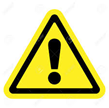  $\overset{\bullet }{\textrm{DCM}}$    :    so here is $\overset{\bullet }{\textrm{DCM}}$  (where    $DCM = {^BR_G}$)

my_DCM_dot = subs(my_DCM_dot, [tmp_old, tmp_old_dot], [tmp_new, tmp_new_dot])

##   $\textrm{DCM}$    :    And as a reminder, here is the DCM  (where    $DCM = {^BR_G}$)

my_DCM = subs(my_DCM, [Ex, Ey, Ez], [E_x  E_y  E_z])

$$my\_DCM = \left(\begin{array}{ccc} \cos\left(\theta \right)+\left(\cos\left(\theta \right)-1\right)\,\left({E_{y}}^{2}+{E_{z}}^{2}-1\right) & E_{z}\,\sin\left(\theta \right)-E_{x}\,E_{y}\,\left(\cos\left(\theta \right)-1\right) & -E_{y}\,\sin\left(\theta \right)-E_{x}\,E_{z}\,\left(\cos\left(\theta \right)-1\right)\\ -E_{z}\,\sin\left(\theta \right)-E_{x}\,E_{y}\,\left(\cos\left(\theta \right)-1\right) & \cos\left(\theta \right)-{E_{y}}^{2}\,\left(\cos\left(\theta \right)-1\right) & E_{x}\,\sin\left(\theta \right)-E_{y}\,E_{z}\,\left(\cos\left(\theta \right)-1\right)\\ E_{y}\,\sin\left(\theta \right)-E_{x}\,E_{z}\,\left(\cos\left(\theta \right)-1\right) & -E_{x}\,\sin\left(\theta \right)-E_{y}\,E_{z}\,\left(\cos\left(\theta \right)-1\right) & \cos\left(\theta \right)-{E_{z}}^{2}\,\left(\cos\left(\theta \right)-1\right) \end{array}\right)$$

## Recall what we know about   $\textrm{DCM},\;\;\;\overset{\bullet }{\textrm{DCM}} ,\;\;\;\textrm{and}\;\;\omega_B$

According to the derivation in [`bh_explore_DCM_rate.mlx`](matlab:  edit bh_explore_DCM_rate.mlx)`, `the angular velocity vector $\omega_B$ (expressed in components of a BODY fixed frame) is related to the $\textrm{DCM}$ and the $\overset{\bullet }{\textrm{DCM}}$ via the relationship:

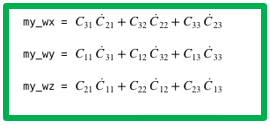

So let's define 

syms omega_x  omega_y  omega_z
          
EQ_wx = omega_x == my_DCM(3,1)*my_DCM_dot(2,1)  +  my_DCM(3,2)*my_DCM_dot(2,2)  + my_DCM(3,3)*my_DCM_dot(2,3);
EQ_wy = omega_y == my_DCM(1,1)*my_DCM_dot(3,1)  +  my_DCM(1,2)*my_DCM_dot(3,2)  + my_DCM(1,3)*my_DCM_dot(3,3);
EQ_wz = omega_z == my_DCM(2,1)*my_DCM_dot(1,1)  +  my_DCM(2,2)*my_DCM_dot(1,2)  + my_DCM(2,3)*my_DCM_dot(1,3);
EQ_mag = 0      == 2*E_x*E_dot_x  +  2*E_y*E_dot_y  +  2*E_z*E_dot_z;

assume(E_x^2 + E_y^2 + E_z^2 == 1)

## Now let's solve for the derivatives of our Eigenaxis parameters

Given that:

- 
$$\textrm{DCM}=f\left(\theta ,E_X \;\;,E_Y ,E_Z \right)$$


- 
$$\overset{\bullet }{\textrm{DCM}} =g\left(\theta ,E_X \;\;,E_Y ,E_Z ,\;\dot{\theta} ,\dot{E_X } \;\;,\dot{E_Y } ,\dot{{\;E}_Z } \right)$$


We should be able to use our "green equations"  to help us solve for

- 
$$\dot{\theta} \;\;,\dot{\;\;E_X } \;\;,\;\;\dot{E_Y } \;\;,\;\dot{{\;E}_Z }$$


S = solve([EQ_wx, EQ_wy, EQ_wz, EQ_mag], [theta_dot, E_dot_x, E_dot_y, E_dot_z] )

S = struct with fields:
    theta_dot: (omega_y*E_x^5*E_z*cos(theta)^3*sin(theta) - 3*omega_y*E_x^5*E_z*cos(theta)^2*sin(theta) + 3*omega_y*E_x^5*E_z*cos(theta)*sin(theta) - omega_y*E_x^5*E_z*sin(theta) + omega_y*E_x^4*E_y*E_z^2*cos(theta)^4 - 4*omega_y*E_x^4*E_y*E_z^2*cos(…
      E_dot_x: -(omega_y*E_x^4*E_y^2*E_z*cos(theta)^2*sin(theta)^2 - 2*omega_y*E_x^4*E_y^2*E_z*cos(theta)*sin(theta)^2 + omega_y*E_x^4*E_y^2*E_z*sin(theta)^2 + omega_x*E_x^4*E_y^2*cos(theta)^3*sin(theta) - 2*omega_x*E_x^4*E_y^2*cos(theta)^2*sin(theta…
      E_dot_y: (omega_y*E_x^5*E_y*E_z*cos(theta)^2*sin(theta)^2 - 2*omega_y*E_x^5*E_y*E_z*cos(theta)*sin(theta)^2 + omega_y*E_x^5*E_y*E_z*sin(theta)^2 + omega_x*E_x^5*E_y*cos(theta)^3*sin(theta) - 2*omega_x*E_x^5*E_y*cos(theta)^2*sin(theta) + omega_x…
      E_dot_z: -(omega_z*E_x^5*E_y*E_z*cos(theta)^4 - 3*omega_z*E_x^5*E_y*E_z*cos(theta)^3 + 3*omega_z*E_x^5*E_y*E_z*cos(theta)^2 - omega_z*E_x^5*E_y*E_z*cos(theta) - omega_y*E_x^5*E_z^2*cos(theta)^2*sin(theta)^2 + 2*ome

Now collect in the form of $A\ldotp x=b$ where $x={\left\lbrack \omega_x \;\;,\omega_y \;,\omega_z \;\right\rbrack }^T$

[A1,b1] = equationsToMatrix(0 == theta_dot - simplify(S.theta_dot), [omega_x  omega_y  omega_z])

$$A1 = \left(\begin{array}{ccc} E_{x} & E_{y} & E_{z} \end{array}\right)$$

$$b1 = \left(\begin{array}{c} \dot{\theta } \end{array}\right)$$

[A2,b2] = equationsToMatrix(0 == E_dot_x   - simplify(S.E_dot_x), [omega_x  omega_y  omega_z])

$$A2 = \left(\begin{array}{ccc} -\frac{\sin\left(\theta \right)\,{E_{y}}^{2}+\sin\left(\theta \right)\,{E_{z}}^{2}}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{E_{z}-E_{z}\,\cos\left(\theta \right)+E_{x}\,E_{y}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{E_{y}\,\cos\left(\theta \right)-E_{y}+E_{x}\,E_{z}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} \end{array}\right)$$

$$b2 = \left(\begin{array}{c} {\dot{E}}_{x} \end{array}\right)$$

[A3,b3] = equationsToMatrix(0 == E_dot_y   - simplify(S.E_dot_y), [omega_x  omega_y  omega_z])

$$A3 = \left(\begin{array}{ccc} \frac{E_{z}\,\cos\left(\theta \right)-E_{z}+E_{x}\,E_{y}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} & -\frac{\sin\left(\theta \right)-{E_{y}}^{2}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{E_{x}-E_{x}\,\cos\left(\theta \right)+E_{y}\,E_{z}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} \end{array}\right)$$

$$b3 = \left(\begin{array}{c} {\dot{E}}_{y} \end{array}\right)$$


[A4,b4] = equationsToMatrix(0 == E_dot_z   - simplify(S.E_dot_z), [omega_x  omega_y  omega_z])

$$A4 = \left(\begin{array}{ccc} \frac{E_{y}-E_{y}\,\cos\left(\theta \right)+E_{x}\,E_{z}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{E_{x}\,\cos\left(\theta \right)-E_{x}+E_{y}\,E_{z}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} & -\frac{\sin\left(\theta \right)-{E_{z}}^{2}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} \end{array}\right)$$

$$b4 = \left(\begin{array}{c} {\dot{E}}_{z} \end{array}\right)$$

Consolidate:

wb_col = [omega_x ; omega_y ; omega_z];

A1     = simplify(A1);
A2     = simplify(A2);
A3     = simplify(A3);
A4     = simplify(A4);
A      = [A1;A2;A3;A4]

$$A = \left(\begin{array}{ccc} E_{x} & E_{y} & E_{z}\\ -\frac{\sin\left(\theta \right)\,\left({E_{y}}^{2}+{E_{z}}^{2}\right)}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{E_{z}-E_{z}\,\cos\left(\theta \right)+E_{x}\,E_{y}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{E_{y}\,\cos\left(\theta \right)-E_{y}+E_{x}\,E_{z}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)}\\ \frac{E_{z}\,\cos\left(\theta \right)-E_{z}+E_{x}\,E_{y}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{\sin\left(\theta \right)\,\left({E_{y}}^{2}-1\right)}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{E_{x}-E_{x}\,\cos\left(\theta \right)+E_{y}\,E_{z}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)}\\ \frac{E_{y}-E_{y}\,\cos\left(\theta \right)+E_{x}\,E_{z}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{E_{x}\,\cos\left(\theta \right)-E_{x}+E_{y}\,E_{z}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{\sin\left(\theta \right)\,\left({E_{z}}^{2}-1\right)}{2\,\left(\cos\left(\theta \right)-1\right)} \end{array}\right)$$

b = [b1;b2;b3;b4]

$$b = \left(\begin{array}{c} \dot{\theta }\\ {\dot{E}}_{x}\\ {\dot{E}}_{y}\\ {\dot{E}}_{z} \end{array}\right)$$

##  So in summary we have:

- $\left\lbrack \begin{array}{c}
\dot{\theta} \\
\dot{E_X } \\
\dot{E_Y } \\
\dot{E_Z } 
\end{array}\right\rbrack \;=\;A\ldotp x$        where     $x={\left\lbrack \omega_x \;\;,\omega_y \;,\omega_z \;\right\rbrack }^T$

and

A

$$A = \left(\begin{array}{ccc} E_{x} & E_{y} & E_{z}\\ -\frac{\sin\left(\theta \right)\,\left({E_{y}}^{2}+{E_{z}}^{2}\right)}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{E_{z}-E_{z}\,\cos\left(\theta \right)+E_{x}\,E_{y}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{E_{y}\,\cos\left(\theta \right)-E_{y}+E_{x}\,E_{z}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)}\\ \frac{E_{z}\,\cos\left(\theta \right)-E_{z}+E_{x}\,E_{y}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{\sin\left(\theta \right)\,\left({E_{y}}^{2}-1\right)}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{E_{x}-E_{x}\,\cos\left(\theta \right)+E_{y}\,E_{z}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)}\\ \frac{E_{y}-E_{y}\,\cos\left(\theta \right)+E_{x}\,E_{z}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{E_{x}\,\cos\left(\theta \right)-E_{x}+E_{y}\,E_{z}\,\sin\left(\theta \right)}{2\,\left(\cos\left(\theta \right)-1\right)} & \frac{\sin\left(\theta \right)\,\left({E_{z}}^{2}-1\right)}{2\,\left(\cos\left(\theta \right)-1\right)} \end{array}\right)$$

## NOTE the following:

- 
$$\left\lbrack \dot{\theta} ,\dot{E_X } \;\;,\dot{E_Y } ,\dot{{\;E}_Z } \right\rbrack =f\left(\theta ,E_X \;\;,E_Y ,E_Z \right)$$


- All terms in the $A$ co-efficient matrix have singularities when $1=\cos \left(\theta \right)$, ie: $\theta =\frac{\pi }{2}$

- So when $\theta =\frac{\pi }{2}$ we can't compute the Eigenaxis ***rates*** using the body angular velocity $\omega$

- This is kind of similar to the singularity that we also observe from the Euler angle rates when "PITCH=90 degrees" 

- In the next section on **quaternions** you'll see how a variable substitution allows us to eliminate this singularity with the body angular velocity $\omega$ 

## Validate against implementation

Now compare this first principles derivation against the implementation

import bh_rots_PKG.bh_eul_eigenaxis_CLS

OBJ_eig_rot          = bh_eul_eigenaxis_CLS( [E_x; E_y; E_z], theta);
e_dot_col_from_OBJ   = OBJ_eig_rot.calc_e_rates_using_wb(wb_col );

specify constraints

assume(E_x,    'real')
assume(E_y,    'real')
assume(E_z,    'real')
assume(theta, 'real')
assumeAlso(E_x^2 + E_y^2 + E_z^2 == 1)

simplify

e_dot_col_from_OBJ = simplify(e_dot_col_from_OBJ);

Compare hands derivation against implementation

should_be_zero = simplify( A*wb_col - e_dot_col_from_OBJ)

$$should\_be\_zero = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

## Validate against Phillips equation

Given $\left\lbrack \begin{array}{c}
\dot{\theta} \\
\dot{E_X } \\
\dot{E_Y } \\
\dot{E_Z } 
\end{array}\right\rbrack \;=\;A\ldotp x$        where     $x={\left\lbrack \omega_x \;\;,\omega_y \;,\omega_z \;\right\rbrack }^T$

Compare the A matrix against the corresponding one from Phillips against `eqn 11.4.7:`

should_be_zero = simplify(A - LOC_get_phillips_A_eqn() )

$$should\_be\_zero = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

# **Part 2 - **Explore the derivatives of the quaternion parameters

Recall the relationship between the quaternion and the Eigenaxis parameters

- 
$$\left\lbrack \begin{array}{c}
q_0 \\
q_X \\
q_Y \\
q_Z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\cos \left(\frac{\theta }{2}\right)\\
E_X \ldotp \sin \left(\frac{\theta }{2}\right)\\
E_Y \ldotp \sin \left(\frac{\theta }{2}\right)\\
E_Z \ldotp \sin \left(\frac{\theta }{2}\right)
\end{array}\right\rbrack$$
    

where:

- 
$$\;\left(\;1\;\;=\;\;\;{E_X }^2 \;+\;\;\;{E_Y }^2 \;+\;\;{E_Z }^2 \;\right)\;\;\;\;\;\textrm{and}\;\;\;\;\left(\;1\;\;=\;\;{q_0 }^2 +\;\;\;\;{q_X }^2 \;+\;\;\;{q_Y }^2 \;+\;\;{q_Z }^2 \;\right)$$


Now applying the derivative chain rule gives us:

- 
$$\left\lbrack \begin{array}{c}
\dot{q_0 } \\
\dot{q_X } \\
\dot{q_Y } \\
\dot{q_Z } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\sin \left(\frac{\theta }{2}\right)\\
E_X \ldotp \cos \left(\frac{\theta }{2}\right)\\
E_Y \ldotp \cos \left(\frac{\theta }{2}\right)\\
E_Z \ldotp \cos \left(\frac{\theta }{2}\right)
\end{array}\right\rbrack \ldotp \frac{\dot{\theta} }{2}\;\;\;+\;\;\;\left\lbrack \begin{array}{c}
0\\
\dot{E_X } \ldotp \sin \left(\frac{\theta }{2}\right)\\
\dot{E_Y } \ldotp \sin \left(\frac{\theta }{2}\right)\\
\dot{E_Z } \ldotp \sin \left(\frac{\theta }{2}\right)
\end{array}\right\rbrack$$


Which can be written in matrix form as:

- 
$$\left\lbrack \begin{array}{c}
\dot{q_0 } \\
\dot{q_X } \\
\dot{q_Y } \\
\dot{q_Z } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
-\frac{1}{2}\ldotp \sin \left(\frac{\theta }{2}\right) & 0 & 0 & 0\\
\frac{E_X }{2}\ldotp \cos \left(\frac{\theta }{2}\right) & \sin \left(\frac{\theta }{2}\right) & 0 & 0\\
\frac{E_Y }{2}\ldotp \cos \left(\frac{\theta }{2}\right) & 0 & \sin \left(\frac{\theta }{2}\right) & 0\\
\frac{E_Z }{2}\ldotp \cos \left(\frac{\theta }{2}\right) & 0 & 0 & \sin \left(\frac{\theta }{2}\right)
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\dot{\theta} \\
\dot{E_X } \\
\dot{E_Y } \\
\dot{E_Z } 
\end{array}\right\rbrack \;\;\;=\;\;\;A_q \;\ldotp \left\lbrack \begin{array}{c}
\dot{\theta} \\
\dot{E_X } \\
\dot{E_Y } \\
\dot{E_Z } 
\end{array}\right\rbrack \;$$


We already have the following symbols:

Define some new ones:

syms     q_0       q_x       q_y        q_z

So let's define the MATRIX co-efficient defined above:

ct2 = cos(theta/2);
st2 = sin(theta/2);

A_q = [     (-st2/2),   (0),   (0),   (0); 
         (ct2*E_x/2), (st2),   (0),   (0); 
         (ct2*E_y/2),   (0), (st2),   (0); 
         (ct2*E_z/2),   (0),   (0), (st2); 
      ];

So utilising the results from our Eigenrates derivation, we can write:

- 
$$\left\lbrack \begin{array}{c}
\dot{q_0 } \\
\dot{q_X } \\
\dot{q_Y } \\
\dot{q_Z } 
\end{array}\right\rbrack =A_q \;\ldotp \left\lbrack \begin{array}{c}
\dot{\theta} \\
\dot{E_X } \\
\dot{E_Y } \\
\dot{E_Z } 
\end{array}\right\rbrack =A_q \;\ldotp \left\lbrace A\;\ldotp \left\lbrack \begin{array}{c}
\omega_x \\
\omega_y \\
\omega_z 
\end{array}\right\rbrack \right\rbrace \;\;=\;\left\lbrack A_q \;\ldotp A\right\rbrack \;\ldotp \left\lbrack \begin{array}{c}
\omega_x \\
\omega_y \\
\omega_z 
\end{array}\right\rbrack =\;B\;\;\ldotp \;\;\left\lbrack \begin{array}{c}
\omega_x \\
\omega_y \\
\omega_z 
\end{array}\right\rbrack$$


 B = A_q * A;
 B = simplify(B)

$$B = \left(\begin{array}{ccc} -\frac{E_{x}\,\sin\left(\frac{\theta }{2}\right)}{2} & -\frac{E_{y}\,\sin\left(\frac{\theta }{2}\right)}{2} & -\frac{E_{z}\,\sin\left(\frac{\theta }{2}\right)}{2}\\ \frac{\cos\left(\frac{\theta }{2}\right)}{2} & -\frac{E_{z}\,\sin\left(\frac{\theta }{2}\right)}{2} & \frac{E_{y}\,\sin\left(\frac{\theta }{2}\right)}{2}\\ \frac{E_{z}\,\sin\left(\frac{\theta }{2}\right)}{2} & \frac{\cos\left(\frac{\theta }{2}\right)}{2} & -\frac{E_{x}\,\sin\left(\frac{\theta }{2}\right)}{2}\\ -\frac{E_{y}\,\sin\left(\frac{\theta }{2}\right)}{2} & \frac{E_{x}\,\sin\left(\frac{\theta }{2}\right)}{2} & \frac{\cos\left(\frac{\theta }{2}\right)}{2} \end{array}\right)$$

Or using a change of symbol we can rewrite B as:

tmp_old = [cos(theta/2), (E_x*sin(theta/2)),  (E_y*sin(theta/2)),  (E_z*sin(theta/2)) ];
tmp_new = [        q_0,                q_x,                q_y,                 q_z ];

B       = subs(B, tmp_old, tmp_new);

## So in summary we have:

- 
$$\left\lbrack \begin{array}{c}
\dot{q_0 } \\
\dot{q_X } \\
\dot{q_Y } \\
\dot{q_Z } 
\end{array}\right\rbrack =\;B\;\;\ldotp \;\;\left\lbrack \begin{array}{c}
\omega_x \\
\omega_y \\
\omega_z 
\end{array}\right\rbrack$$


where

B

$$B = \left(\begin{array}{ccc} -\frac{q_{x}}{2} & -\frac{q_{y}}{2} & -\frac{q_{z}}{2}\\ \frac{q_{0}}{2} & -\frac{q_{z}}{2} & \frac{q_{y}}{2}\\ \frac{q_{z}}{2} & \frac{q_{0}}{2} & -\frac{q_{x}}{2}\\ -\frac{q_{y}}{2} & \frac{q_{x}}{2} & \frac{q_{0}}{2} \end{array}\right)$$

We can also express $\dot{q}$ in an alternate form.  Consider the following:

syms q_dot_0       q_dot_x       q_dot_y        q_dot_z

EQ_ANOTHER             =  B*[omega_x; omega_y; omega_z;] == [q_dot_0;  q_dot_x;  q_dot_y;  q_dot_z];
[A_another, b_another] = equationsToMatrix(EQ_ANOTHER, [q_0;  q_x;  q_y;  q_z]);
b_another.'

$$ans = \left(\begin{array}{cccc} {\dot{q}}_{0} & {\dot{q}}_{x} & {\dot{q}}_{y} & {\dot{q}}_{z} \end{array}\right)$$

## So in summary we have:

- 
$$\left\lbrack \begin{array}{c}
\dot{q_0 } \\
\dot{q_X } \\
\dot{q_Y } \\
\dot{q_Z } 
\end{array}\right\rbrack =A_{\textrm{ANOTHER}} \;\;\ldotp \;\;\left\lbrack \begin{array}{c}
q_0 \\
q_x \\
q_y \\
q_z 
\end{array}\right\rbrack$$


where:

A_another

$$A\_another = \left(\begin{array}{cccc} 0 & -\frac{\omega_{x}}{2} & -\frac{\omega_{y}}{2} & -\frac{\omega_{z}}{2}\\ \frac{\omega_{x}}{2} & 0 & \frac{\omega_{z}}{2} & -\frac{\omega_{y}}{2}\\ \frac{\omega_{y}}{2} & -\frac{\omega_{z}}{2} & 0 & \frac{\omega_{x}}{2}\\ \frac{\omega_{z}}{2} & \frac{\omega_{y}}{2} & -\frac{\omega_{x}}{2} & 0 \end{array}\right)$$

# Local Subfunctions ONLY beyond this point

function A = LOC_get_phillips_A_eqn()

  syms E_x  E_y  E_z theta
  
  assume(E_x^2 + E_y^2 + E_z^2 == 1)
  
  C = cos(theta/2);
  S = sin(theta/2);
  
  Exx = -E_x*E_x*C/S;
  Eyy = -E_y*E_y*C/S;
  Ezz = -E_z*E_z*C/S;  
  
  Exy = -E_x*E_y*C/S;
  Exz = -E_x*E_z*C/S; 
  Eyz = -E_y*E_z*C/S;   
    
  A = 0.5 * [       2*E_x,        2*E_y,        2*E_z;
              (Exx + C/S),  (Exy - E_z),  (Exz + E_y);
              (Exy + E_z),  (Eyy + C/S),  (Eyz - E_x);
              (Exz - E_y),  (Eyz + E_x),  (Ezz + C/S);     ]  ;

 % E_dot = A * wb
 %
 %     where
 %
 % E_dot = [  DOT_theta; 
 %            DOT_Ex; 
 %            DOT_Ey; 
 %            DOT_Ez; ] 
          
end